load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

[info_str, cycle_index, summary,VITcharge, VITdischarge,VIT_leng ]  = extract_feature_all_new_bat(1,3,trainData(3));

info_str = 1×4 string array
    "b1c3"    "3"    "3_6C-80PER_3_6C"    "3.6C(80%)-3.6C"


cycle_index = 1175

summary = 	1.0e+03 *

    0.0010    0.0011    0.0000    0.0318    0.0300    0.0347    0.0133    0.0011
    0.0020    0.0011    0.0000    0.0319    0.0300    0.0348    0.0133    0.0011
    0.0030    0.0011    0.0000    0.0319    0.0303    0.0351    0.0134    0.0011
    0.0040    0.0011    0.0000    0.0320    0.0300    0.0350    0.0133    0.0011
    0.0050    0.0011    0.0000    0.0320    0.0303    0.0350    0.0133    0.0011
    0.0060    0.0011    0.0000    0.0319    0.0300    0.0348    0.0134    0.0011
    0.0070    0.0011    0.0000    0.0319    0.0300    0.0347    0.0134    0.0011
    0.0080    0.0011    0.0000    0.0319    0.0301    0.0348    0.0133    0.0011
    0.0090    0.0011    0.0000    0.0319    0.0302    0.0347    0.0133    0.0011
    0.0100    0.0011    0.0000    0.0318    0.0299    0.0348    0.0133    0.0011


VITcharge =     2.0272    2.9501    3.0762    3.1588    3.2189    3.2653    3.3025    3.3294    3.3452    3.3546    3.3614    3.3676    3.3735    3.3792    3.3850    3.3903    3.3956    3.4005    3.4053    3.4098    3.4141    3.4179    3.4213    3.4243    3.4271    3.4295    3.4318    3.4340    3.4361    3.4381    3.4401    3.4420    3.4439    3.4457    3.4475    3.4494    3.4510    3.4528    3.4544    3.4560    3.4577    3.4593    3.4610    3.4626    3.4640    3.4656    3.4670    3.4686    3.4702    3.4717
    2.0264    2.9562    3.0758    3.1585    3.2185    3.2650    3.3021    3.3292    3.3449    3.3539    3.3609    3.3670    3.3729    3.3787    3.3842    3.3896    3.3950    3.3999    3.4046    3.4091    3.4133    3.4171    3.4204    3.4235    3.4261    3.4286    3.4309    3.4330    3.4350    3.4372    3.4391    3.4409    3.4429    3.4447    3.4466    3.4484    3.4501    3.4519    3.4536    3.4552    3.4568    3.4585    3.4600    3.4616    3.4631    3.4647    3.4662    3.4677    3.4

VITdischarge =     3.6001    3.3089    3.2487    3.2182    3.2019    3.1920    3.1854    3.1811    3.1775    3.1745    3.1720    3.1698    3.1677    3.1657    3.1638    3.1620    3.1603    3.1587    3.1569    3.1552    3.1536    3.1520    3.1503    3.1487    3.1470    3.1454    3.1437    3.1420    3.1402    3.1384    3.1367    3.1348    3.1331    3.1310    3.1293    3.1272    3.1253    3.1232    3.1211    3.1189    3.1168    3.1145    3.1124    3.1100    3.1077    3.1054    3.1032    3.1008    3.0984    3.0960
    3.6001    3.3095    3.2493    3.2187    3.2024    3.1926    3.1863    3.1815    3.1781    3.1752    3.1727    3.1704    3.1682    3.1662    3.1644    3.1625    3.1607    3.1590    3.1573    3.1556    3.1540    3.1523    3.1507    3.1489    3.1473    3.1455    3.1440    3.1421    3.1404    3.1387    3.1368    3.1350    3.1331    3.1313    3.1292    3.1273    3.1254    3.1232    3.1211    3.1191    3.1168    3.1147    3.1124    3.1102    3.1078    3.1056    3.1031    3.1008    

VIT_leng = 100

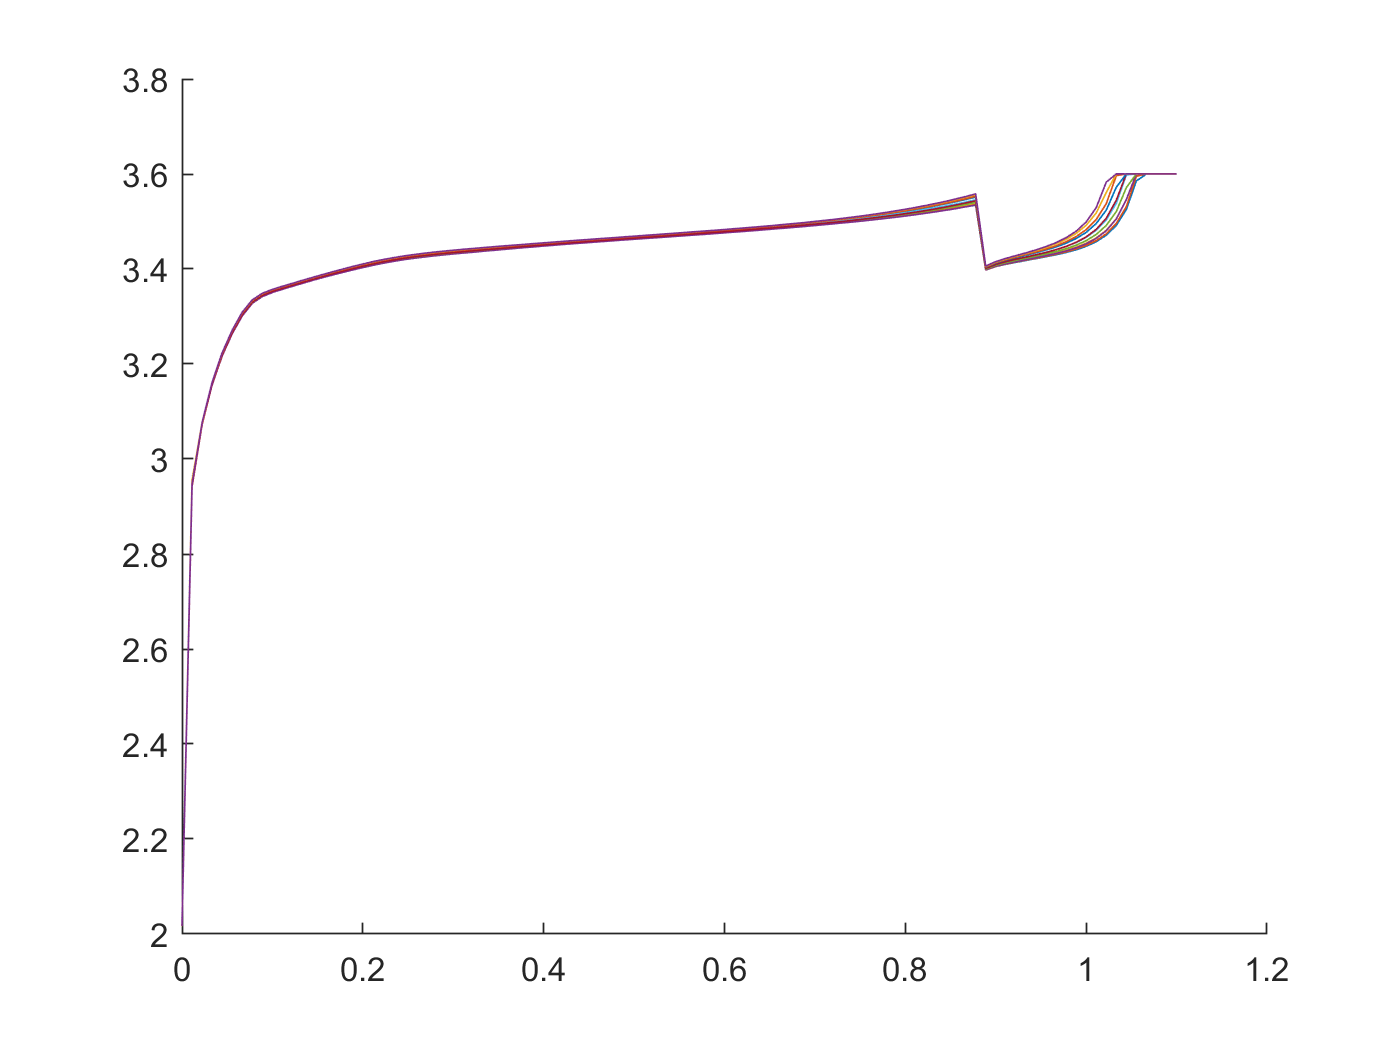


gap = 100;

Vindex=[1:VIT_leng];
Iindex=[VIT_leng+1:VIT_leng+VIT_leng];
Tindex=[VIT_leng+VIT_leng+1:VIT_leng+VIT_leng+VIT_leng];



% 충전전압 유의미
% 이것만으로 충전 패턴을 찾을 수 있슴.
figure
hold on
x = linspace(0.0,1.1,VIT_leng);
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VITcharge(i,Vindex))
    end
end
hold off

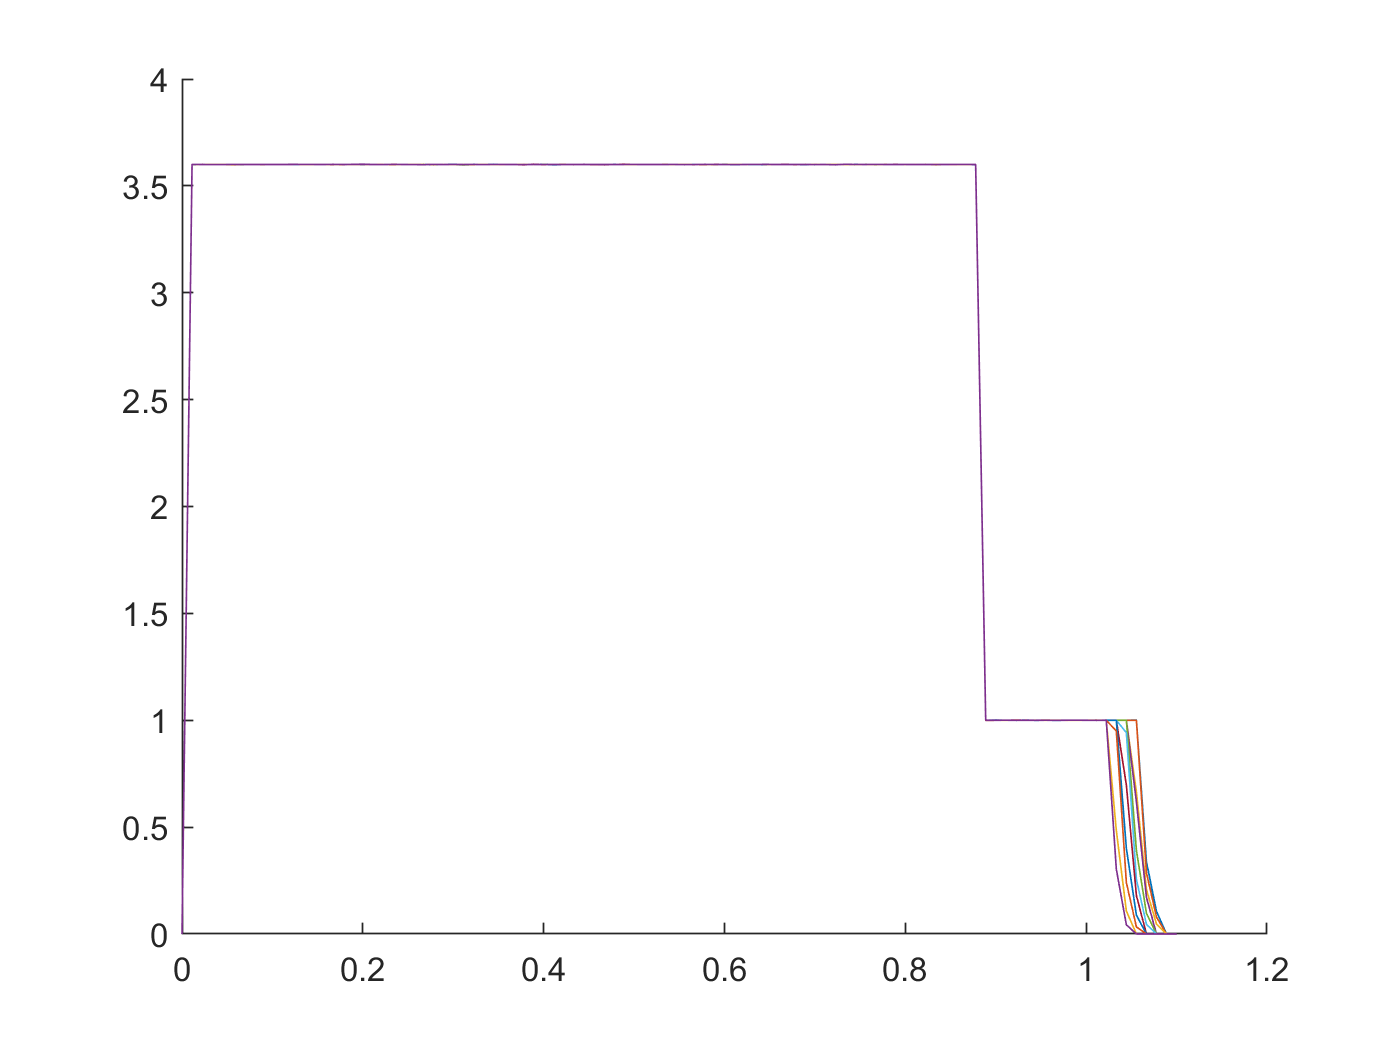

% 충전전류 무의미
figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VITcharge(i,Iindex))
    end
end
hold off

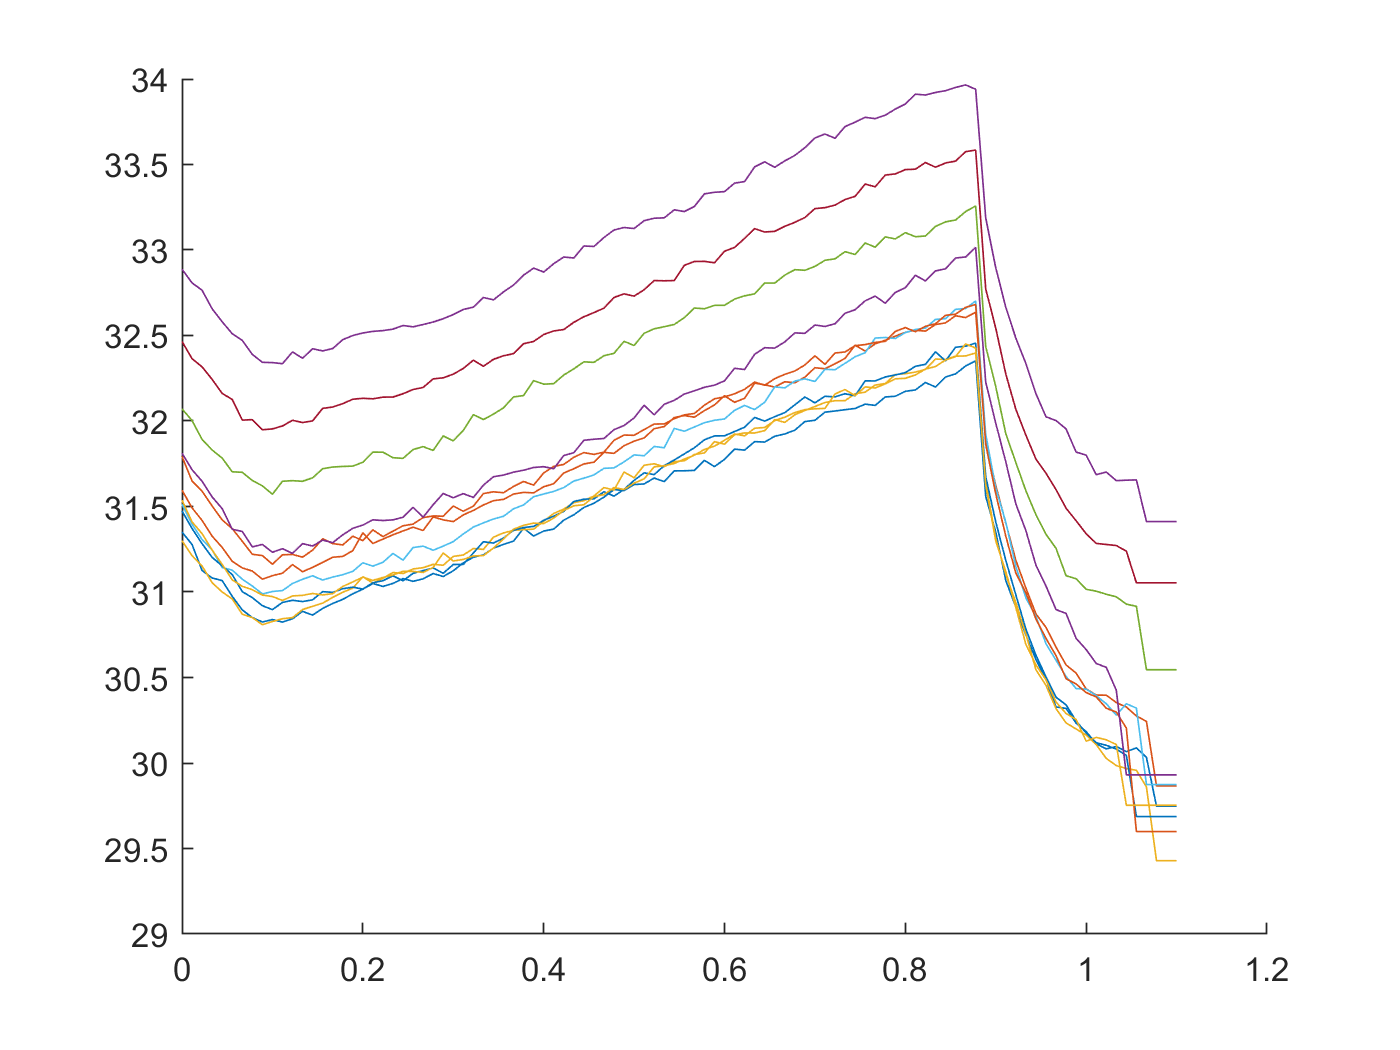

% 충전 온도 유의미
figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VITcharge(i,Tindex))
    end
end
hold off

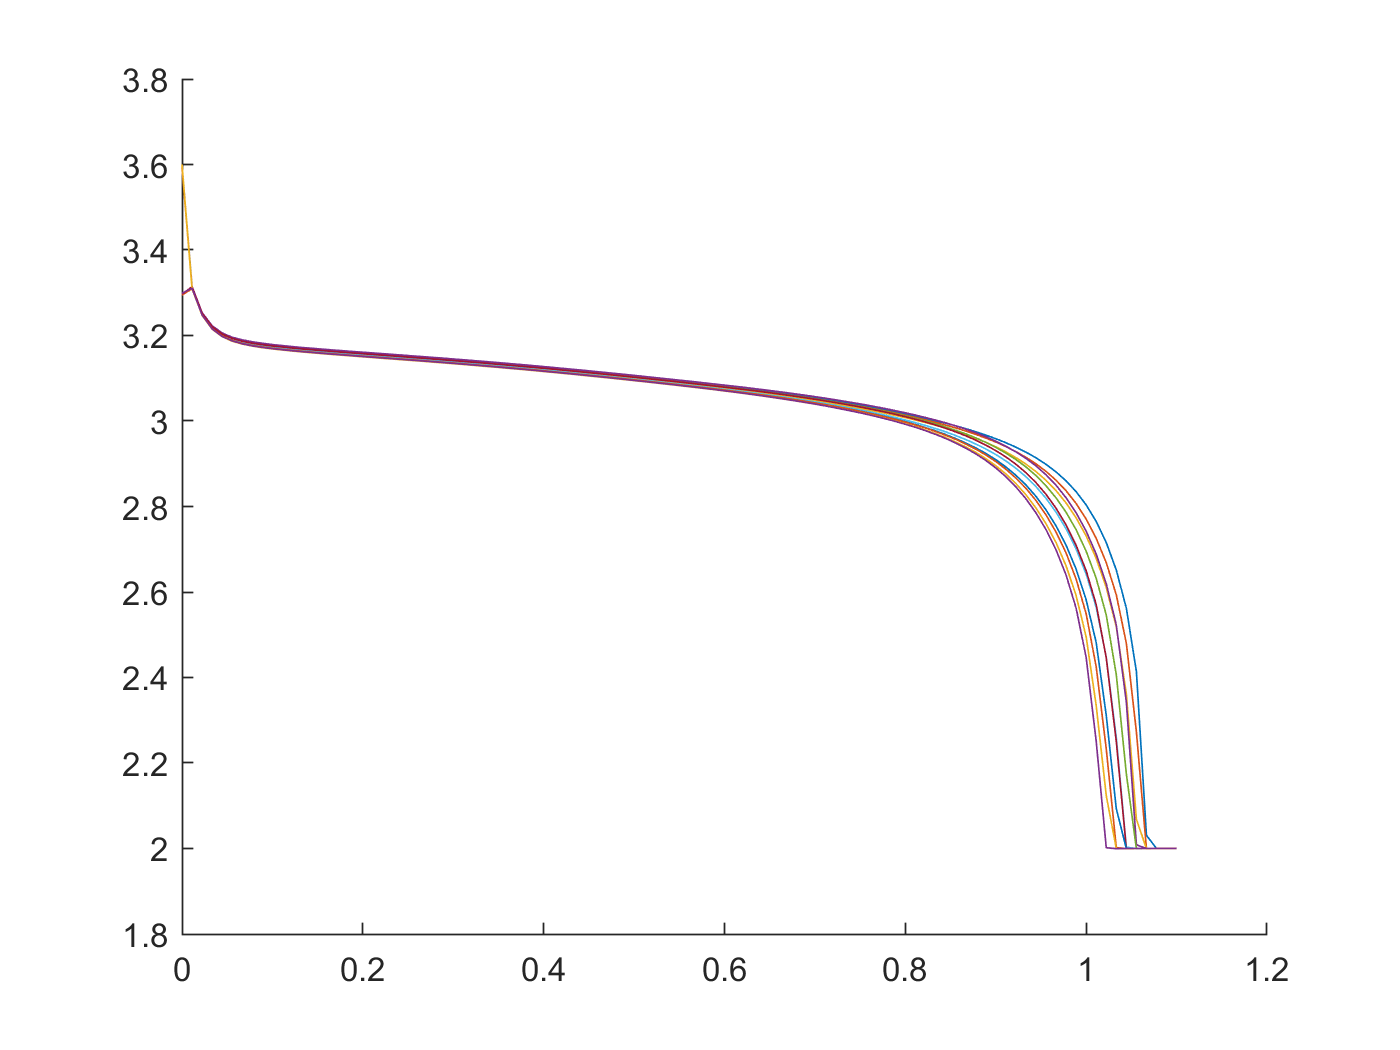


figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VITdischarge(i,Vindex))
    end
end
hold off

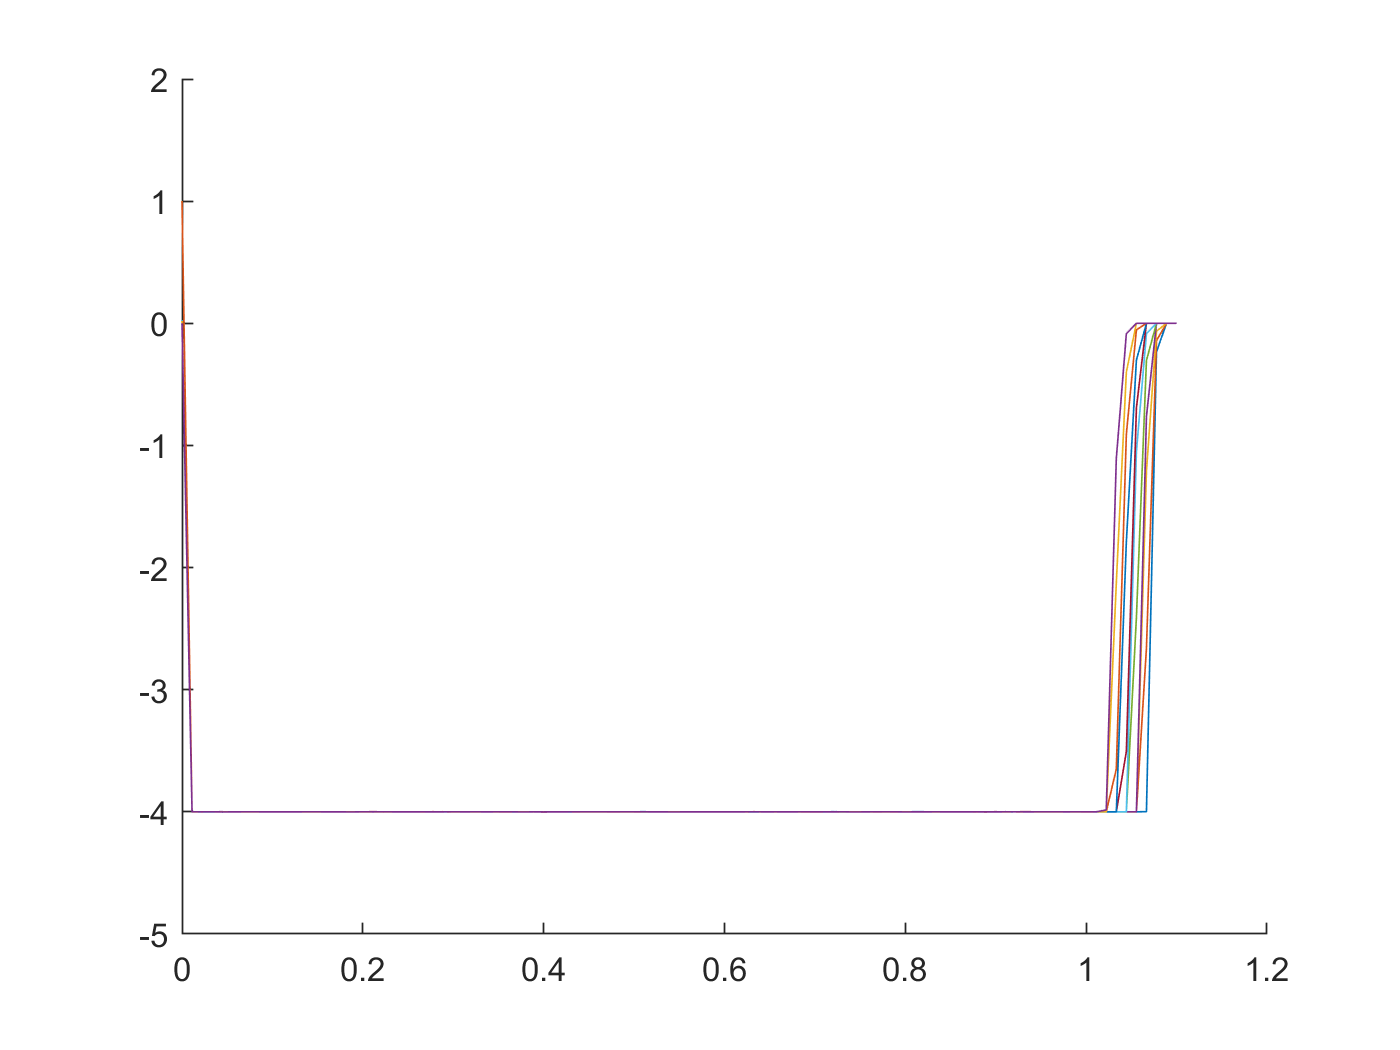

% 방전전류는 무시해도 된다. 단지 SOH만 보여준다.
figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VITdischarge(i,Iindex))
    end
end
hold off

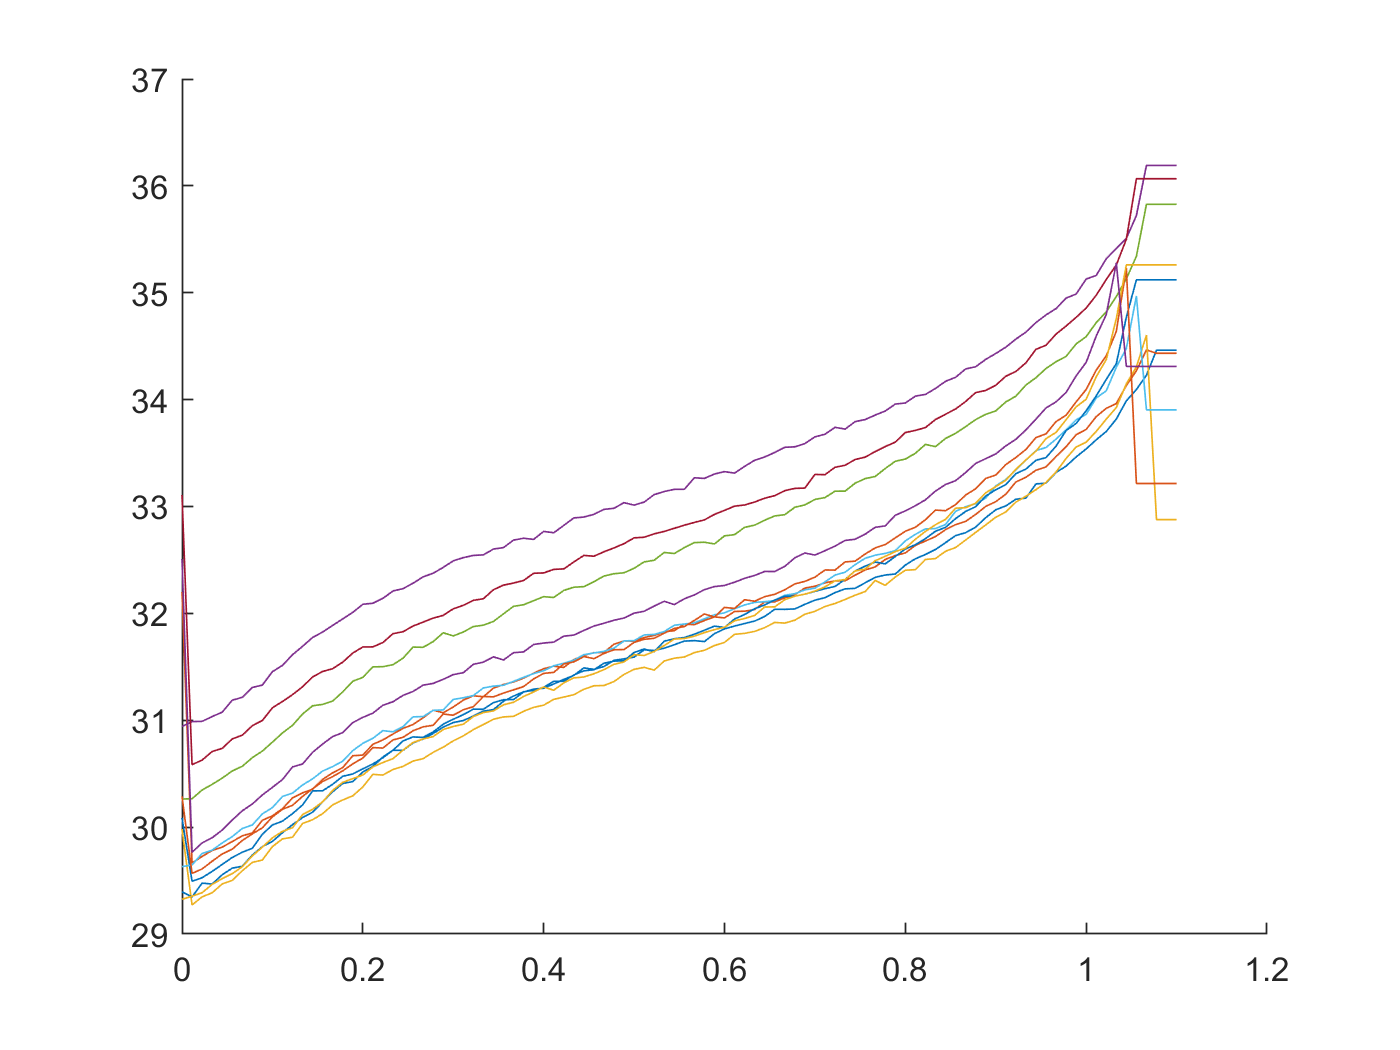


% 방전온도는 유의미하다. 단 마지막쪽은 데이타 편집이 필요하다.
figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VITdischarge(i,Tindex))
    end
end
hold off

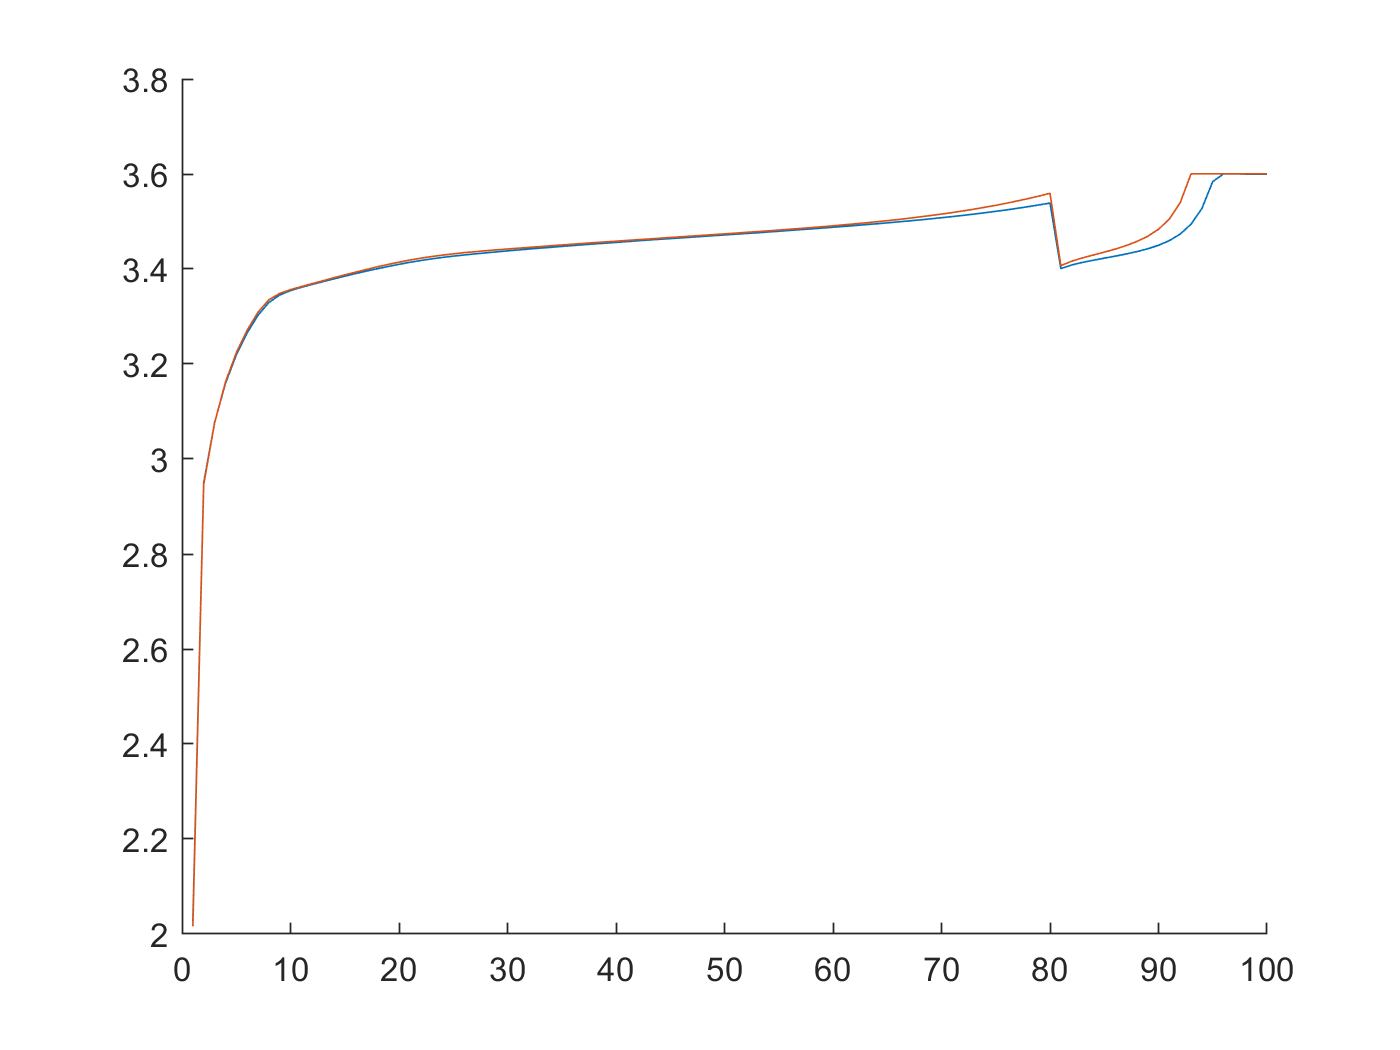

figure
hold on
plot(VITcharge(1,1:100))
plot(VITcharge(cycle_index,1:100))
hold off

# 데이타 처리 - Ah / SOC /Time 단위

1)  Ah 단위 

    시간이 지날수록 rated 인 1.1Ah 에 미치치 못하는 것이 생기고 이때 SOC가 100 이후부터는 데이타가 없다.

2) SOC 단위

=> 선정 - 이것으로 테스트 한다.

3) 시간단위

    각 배터리의 사이클이 증가함에 따라 테스트가 빨리 끝나 뒤쪽의 시간에 대한 데이타가 NaN 으로 처리된다. Ah단위와 비슷. 이때는 전체 시간을 N으로 나누어서 처리하게 되는데 결국 SOC 단위와 비슷해 진다.

[info_str, cycle_index, summary,chargeI,dischargeI,VTcharge, VTdischarge,VT_leng ]  = extract_feature_all_new_bat_v2(1,3,trainData(3));
[info_str1, cycle_index1, summary1,chargeI1,dischargeI1,VTcharge1, VTdischarge1,VT_leng1 ]  = extract_feature_all_new_bat_soc_v2(1,3,trainData(3));


gap = 100;

Vindex=[1:VT_leng];
Tindex=[VT_leng+1:VT_leng+VT_leng];
x = linspace(0.0,1.1,VT_leng);
x1 = linspace(0.0,1.0,VT_leng);

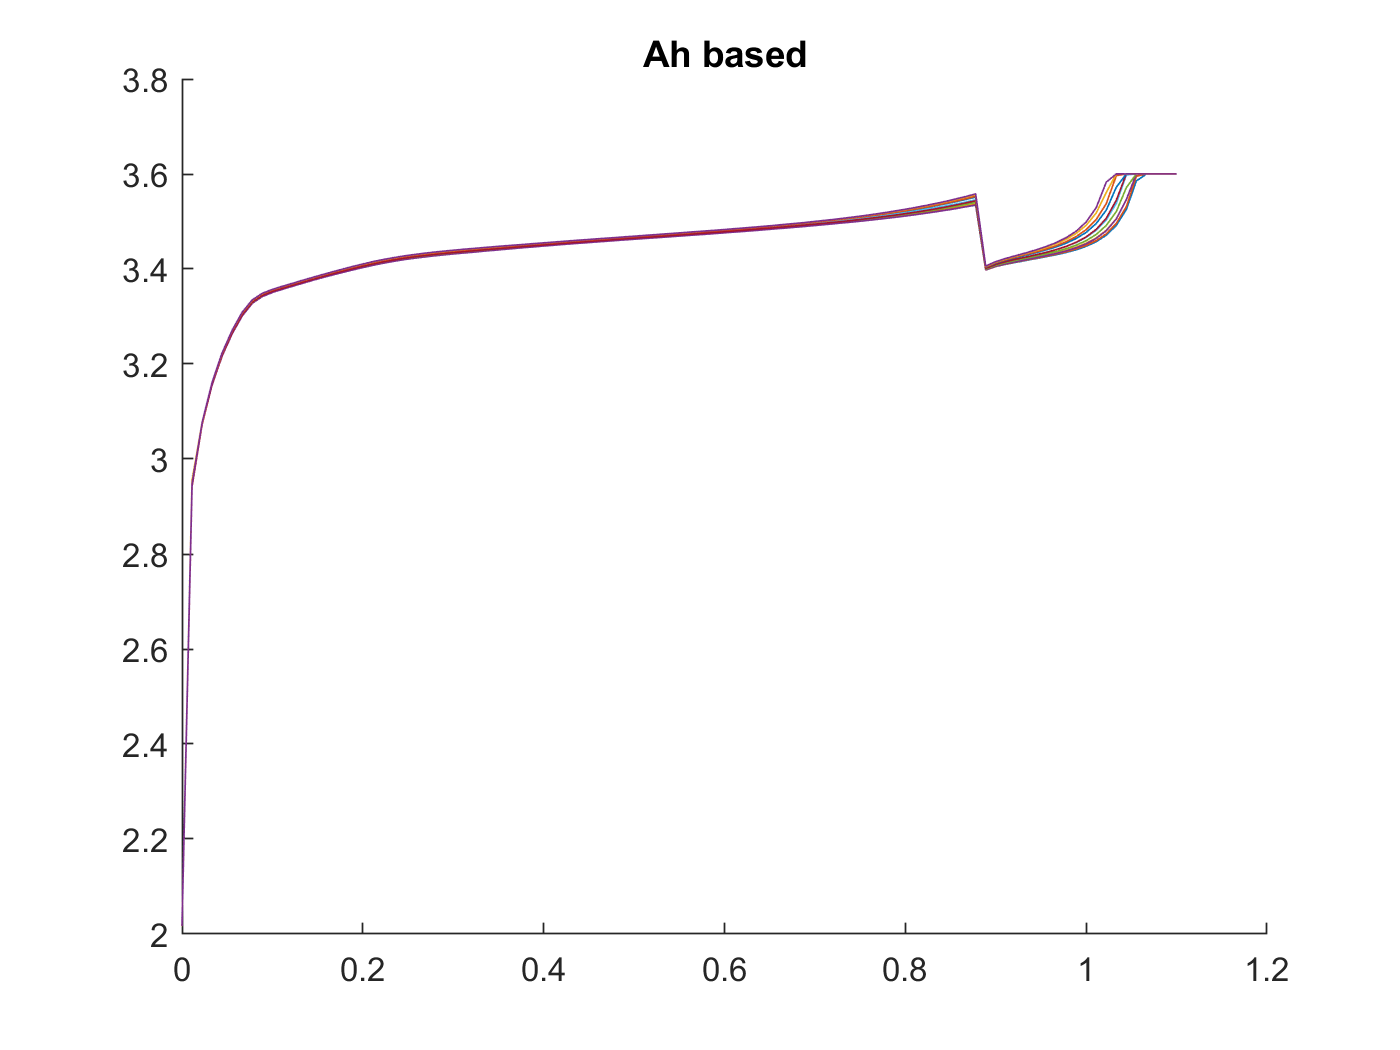



% 충전전압 유의미
% 이것만으로 충전 패턴을 찾을 수 있슴.
figure
hold on
x = linspace(0.0,1.1,VT_leng);
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VTcharge(i,Vindex))
    end
end
hold off
title("Ah based")

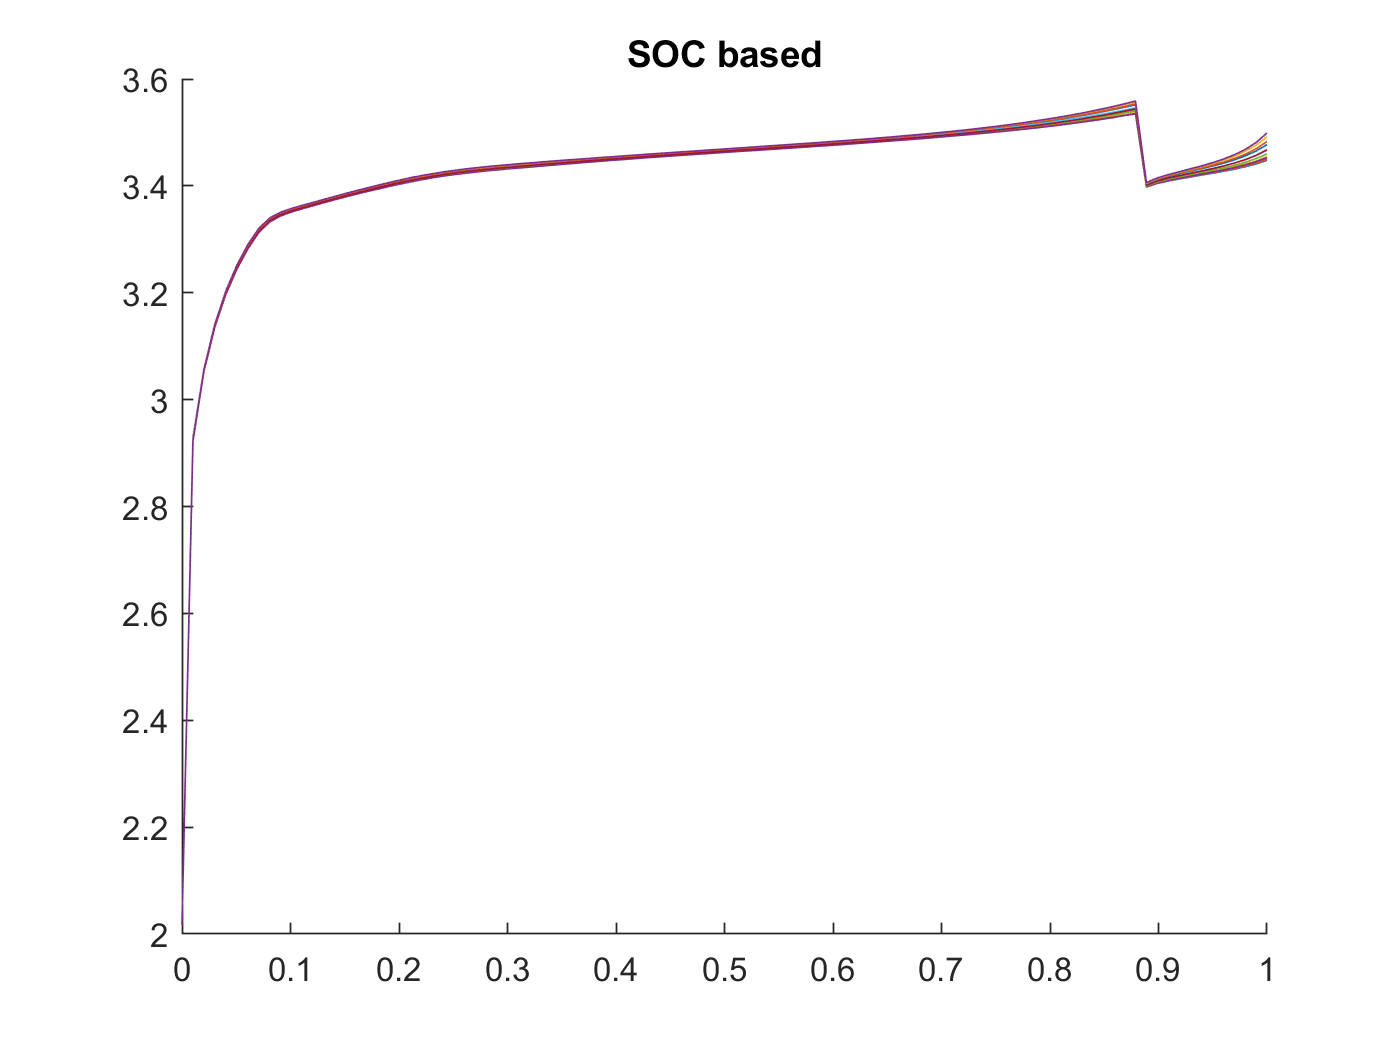


figure
hold on

for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x1, VTcharge1(i,Vindex))
    end
end
hold off
title("SOC based")

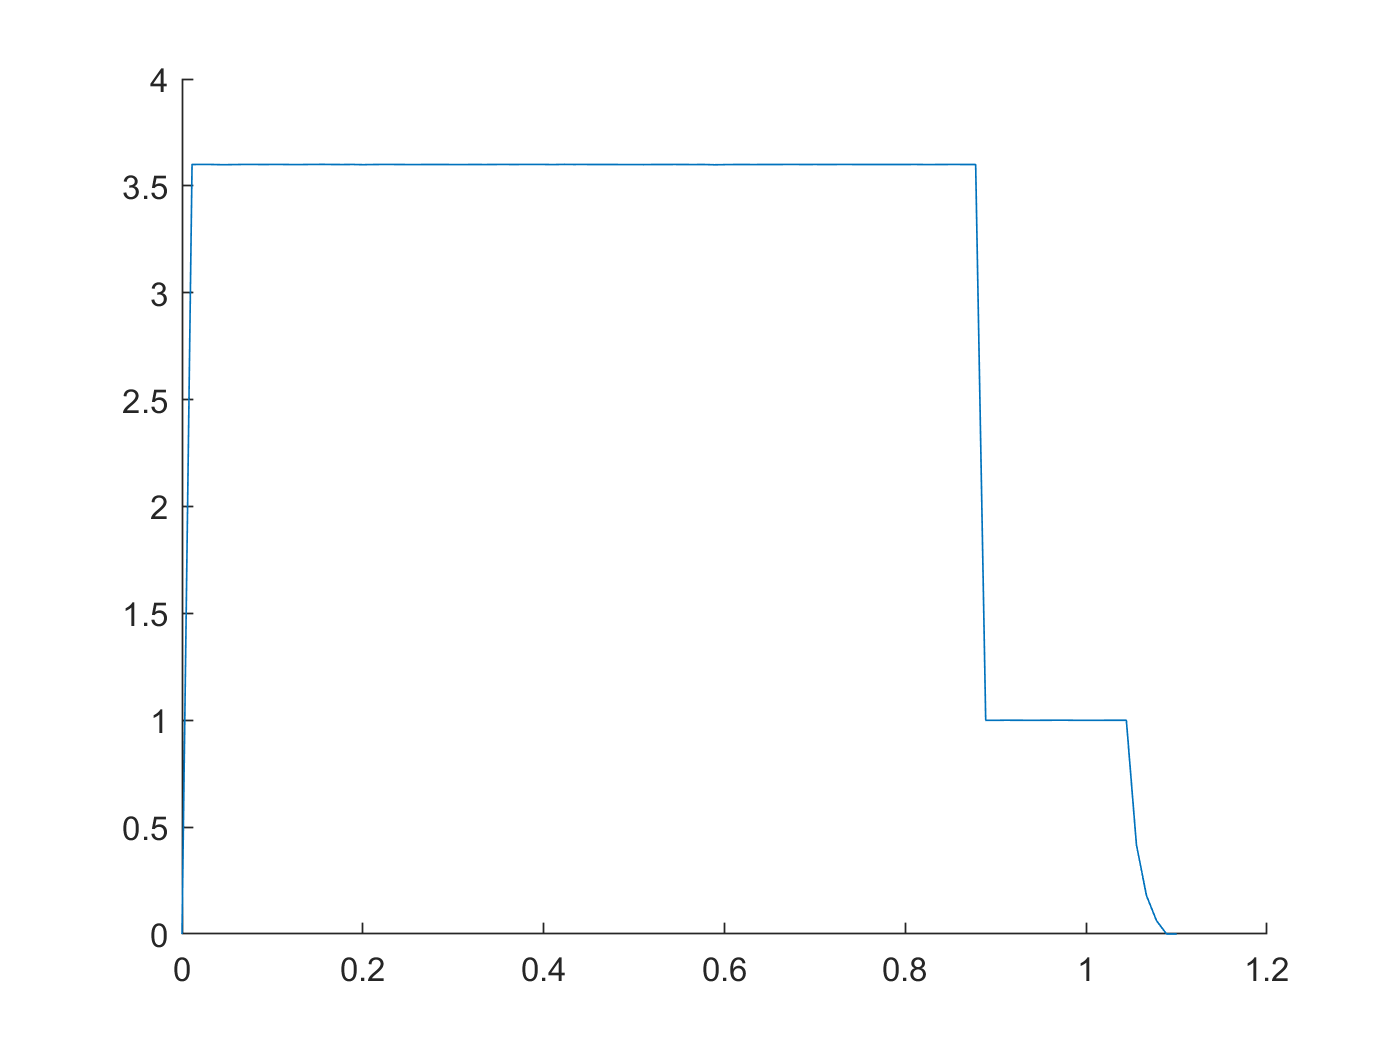


% 충전전류 무의미
figure
hold on
plot(x, chargeI)
hold off

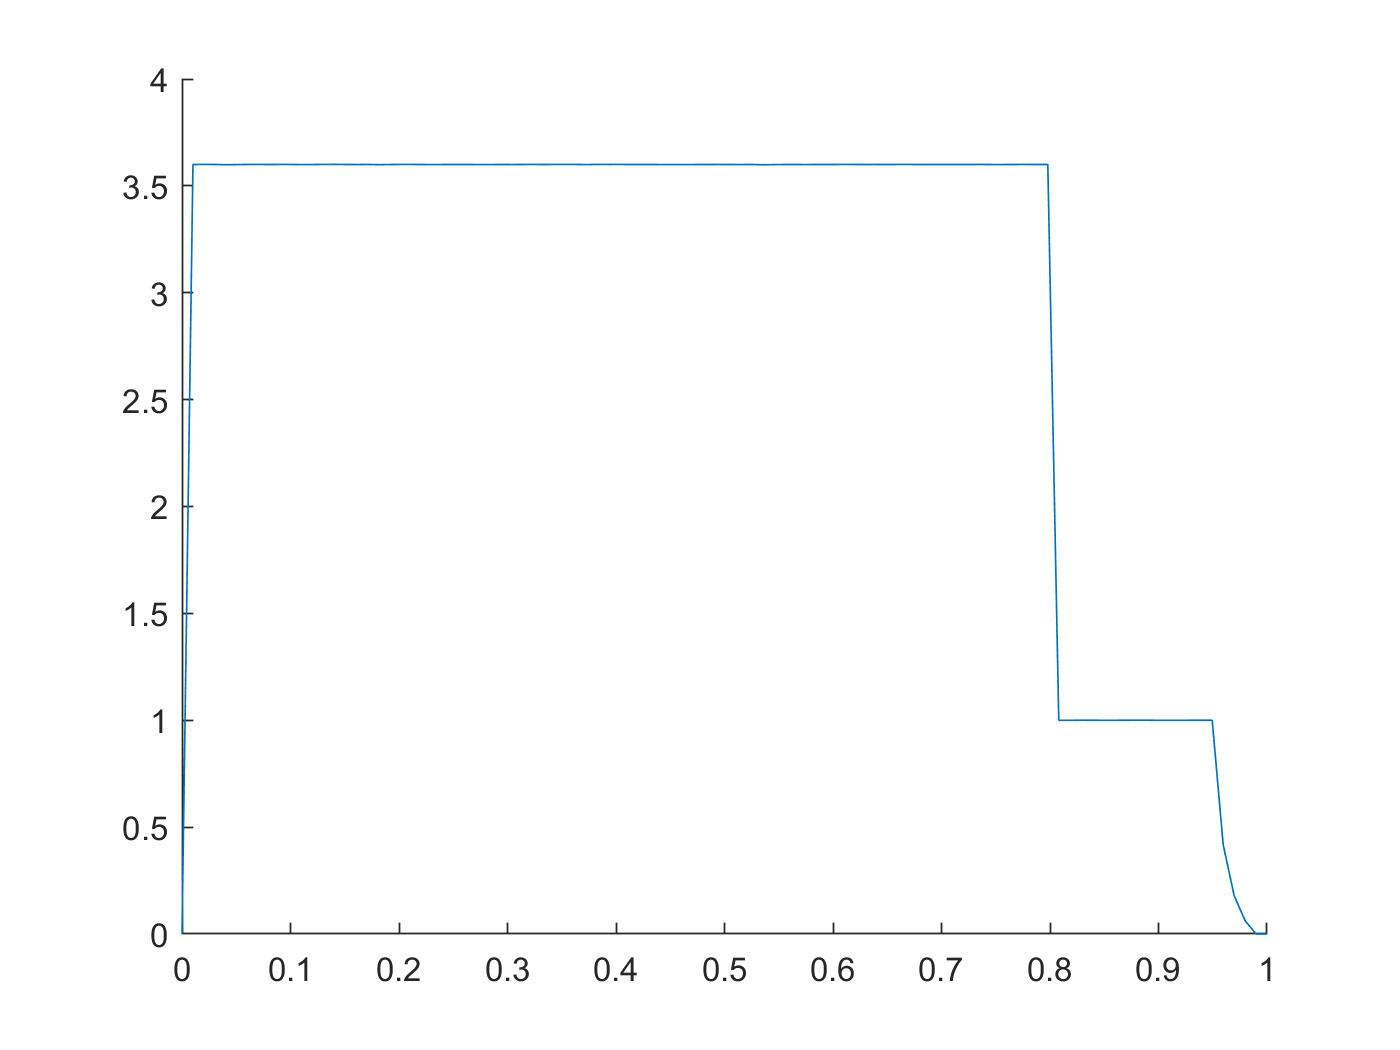

figure
hold on
plot(x1, chargeI)
hold off


% 충전 온도 유의미
figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VTcharge(i,Tindex))
    end
end
hold off

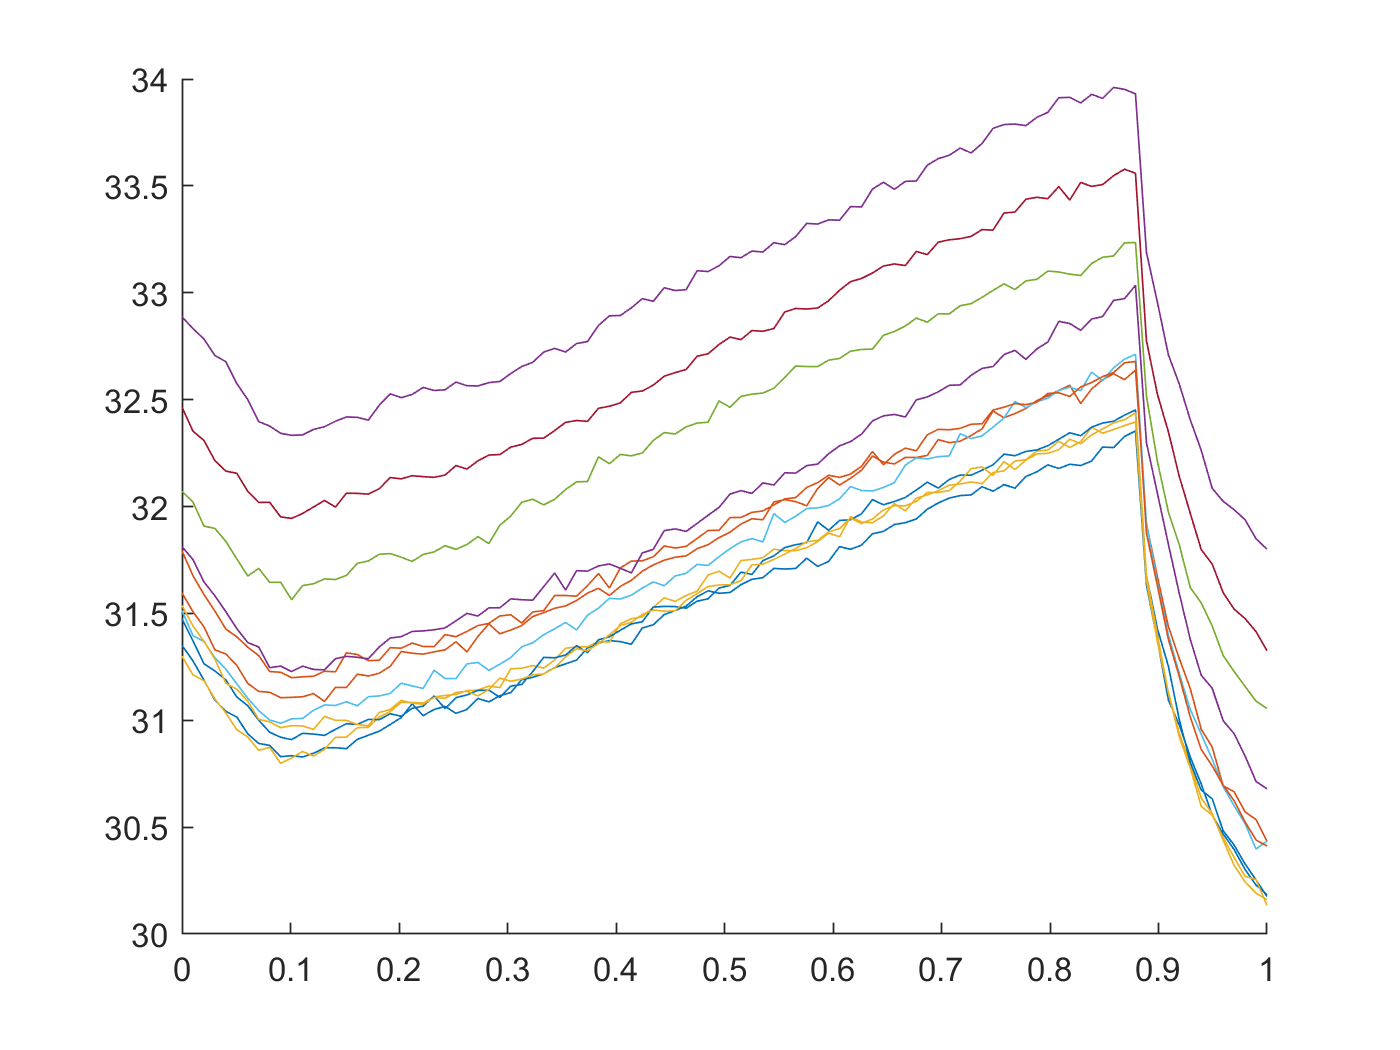


figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x1, VTcharge1(i,Tindex))
    end
end
hold off


figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VTdischarge(i,Vindex))
    end
end
hold off

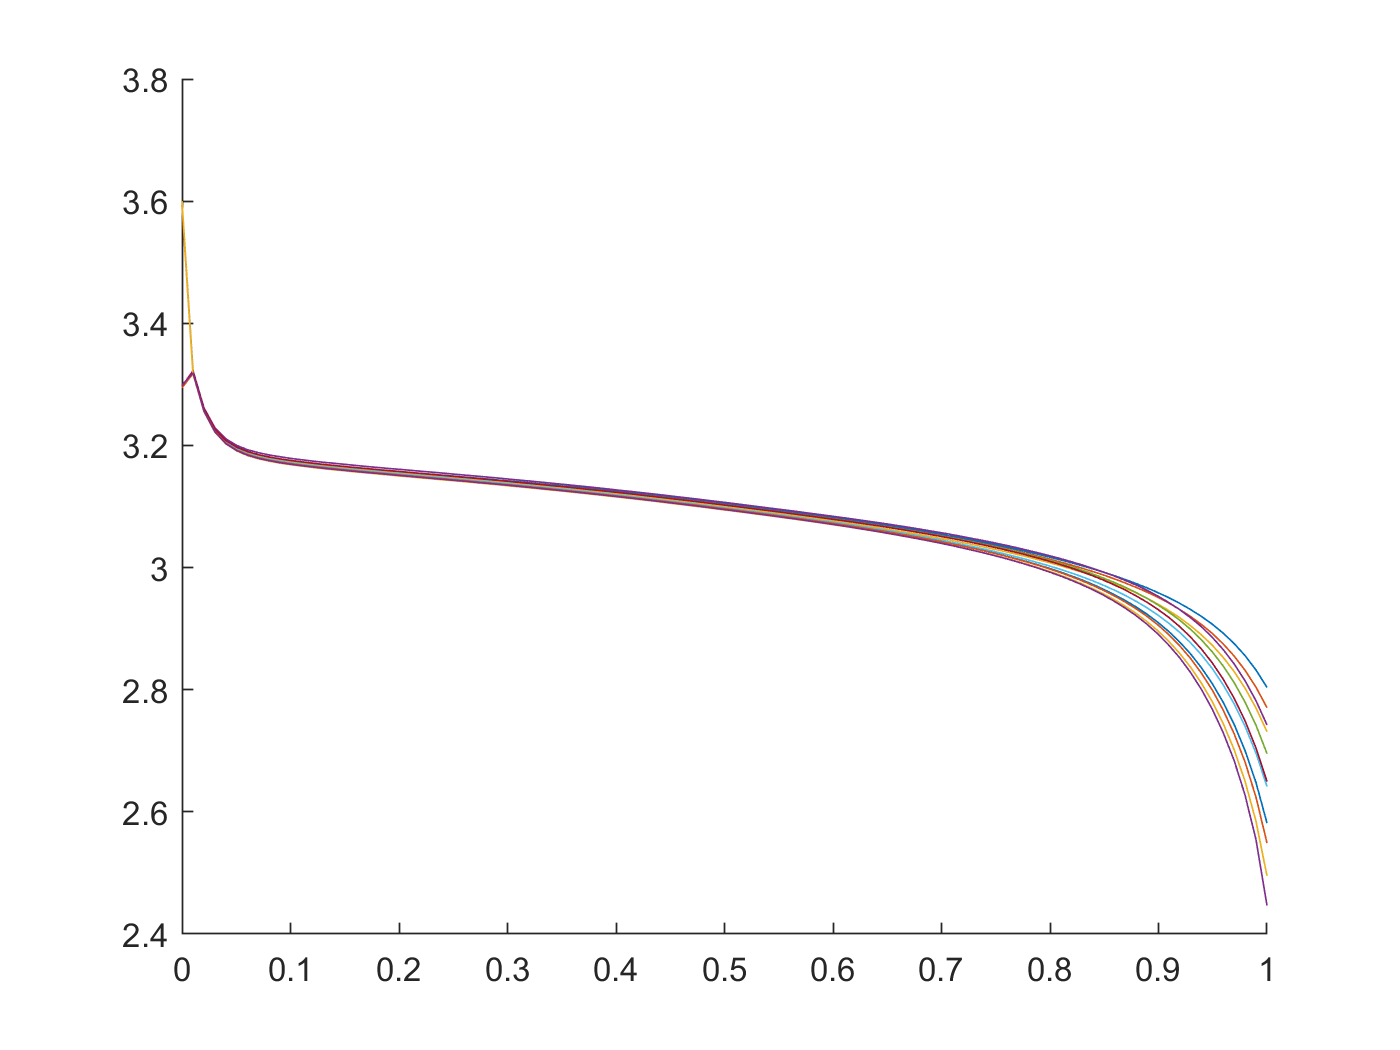


figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x1, VTdischarge1(i,Vindex))
    end
end
hold off

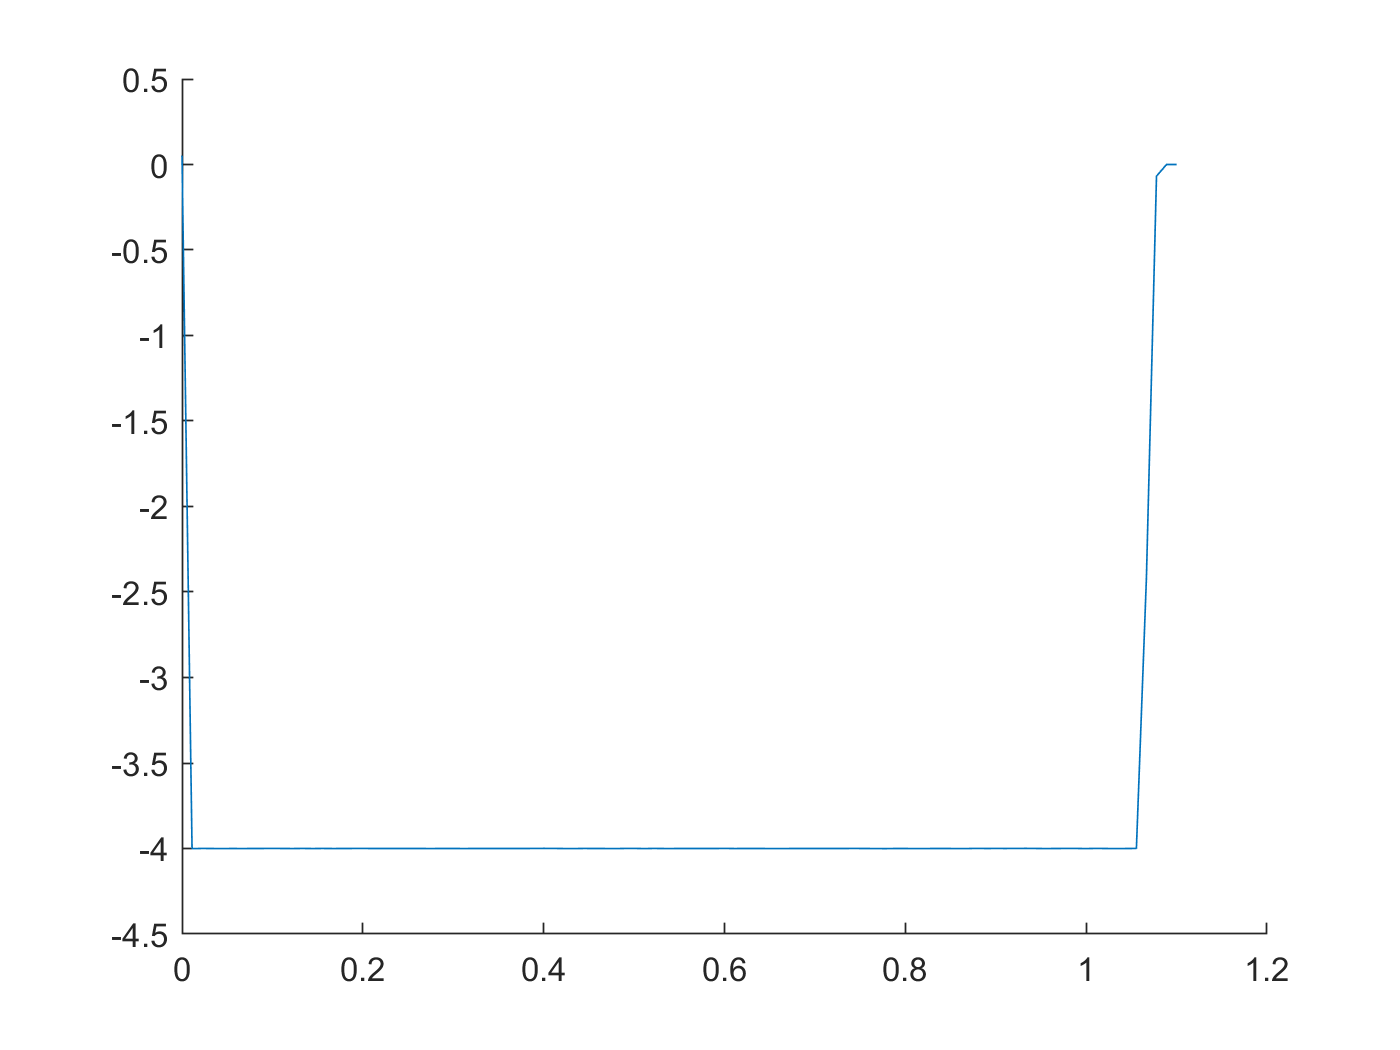

% 방전전류는 무시해도 된다. 단지 SOH만 보여준다.
figure
hold on
plot(x, dischargeI)
hold off

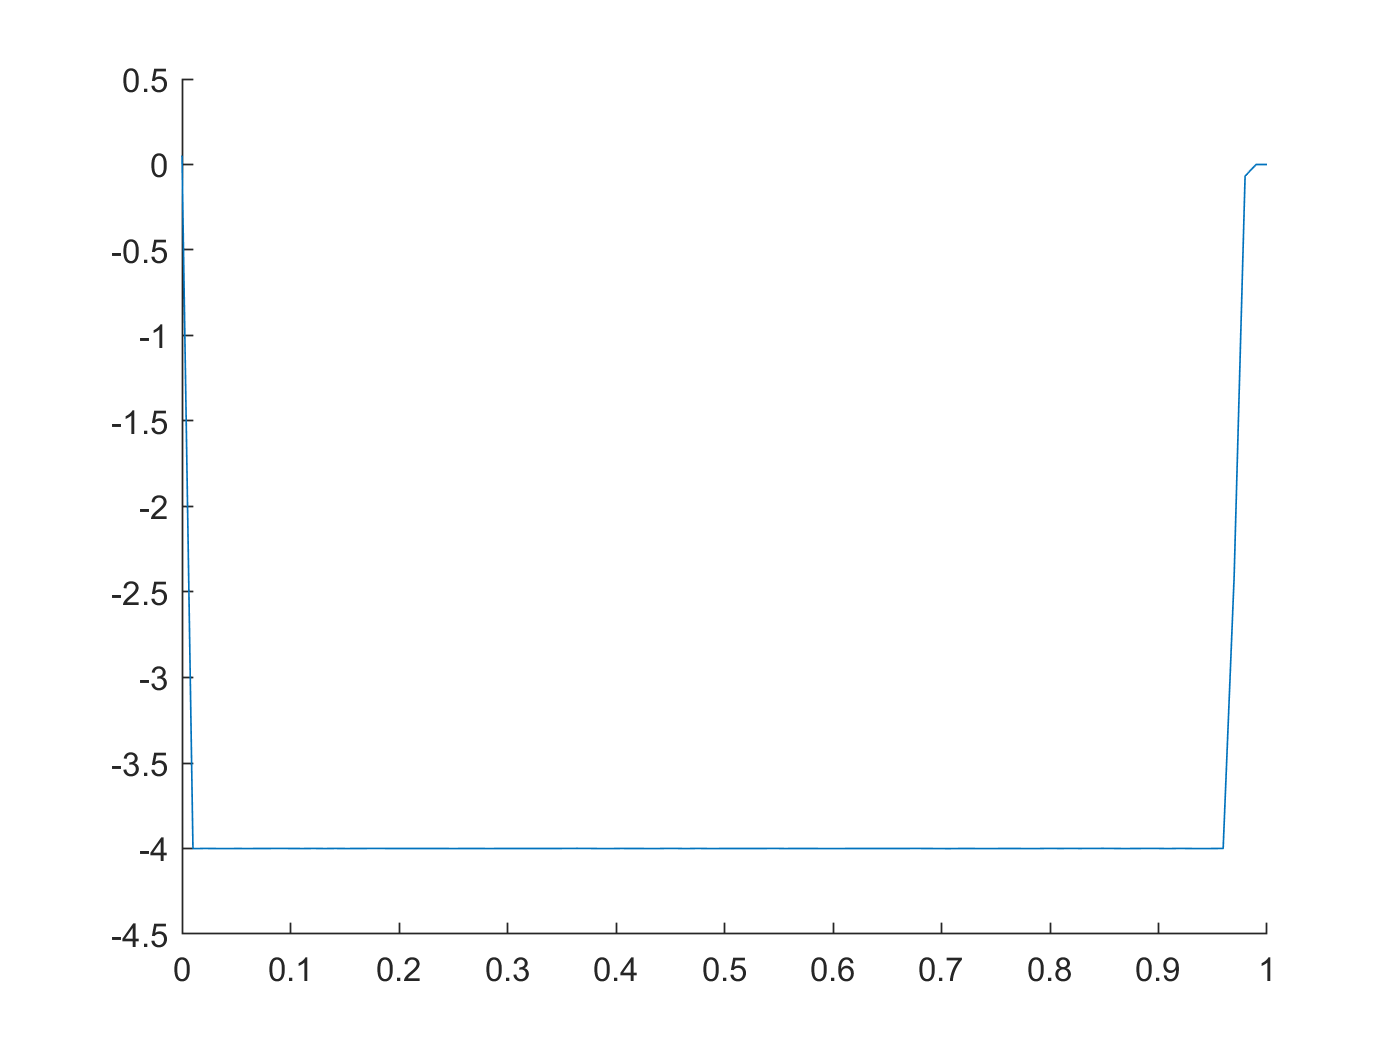

figure
hold on
plot(x1, dischargeI)
hold off


% 방전온도는 유의미하다. 단 마지막쪽은 데이타 편집이 필요하다.
figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x, VTdischarge(i,Tindex))
    end
end
hold off

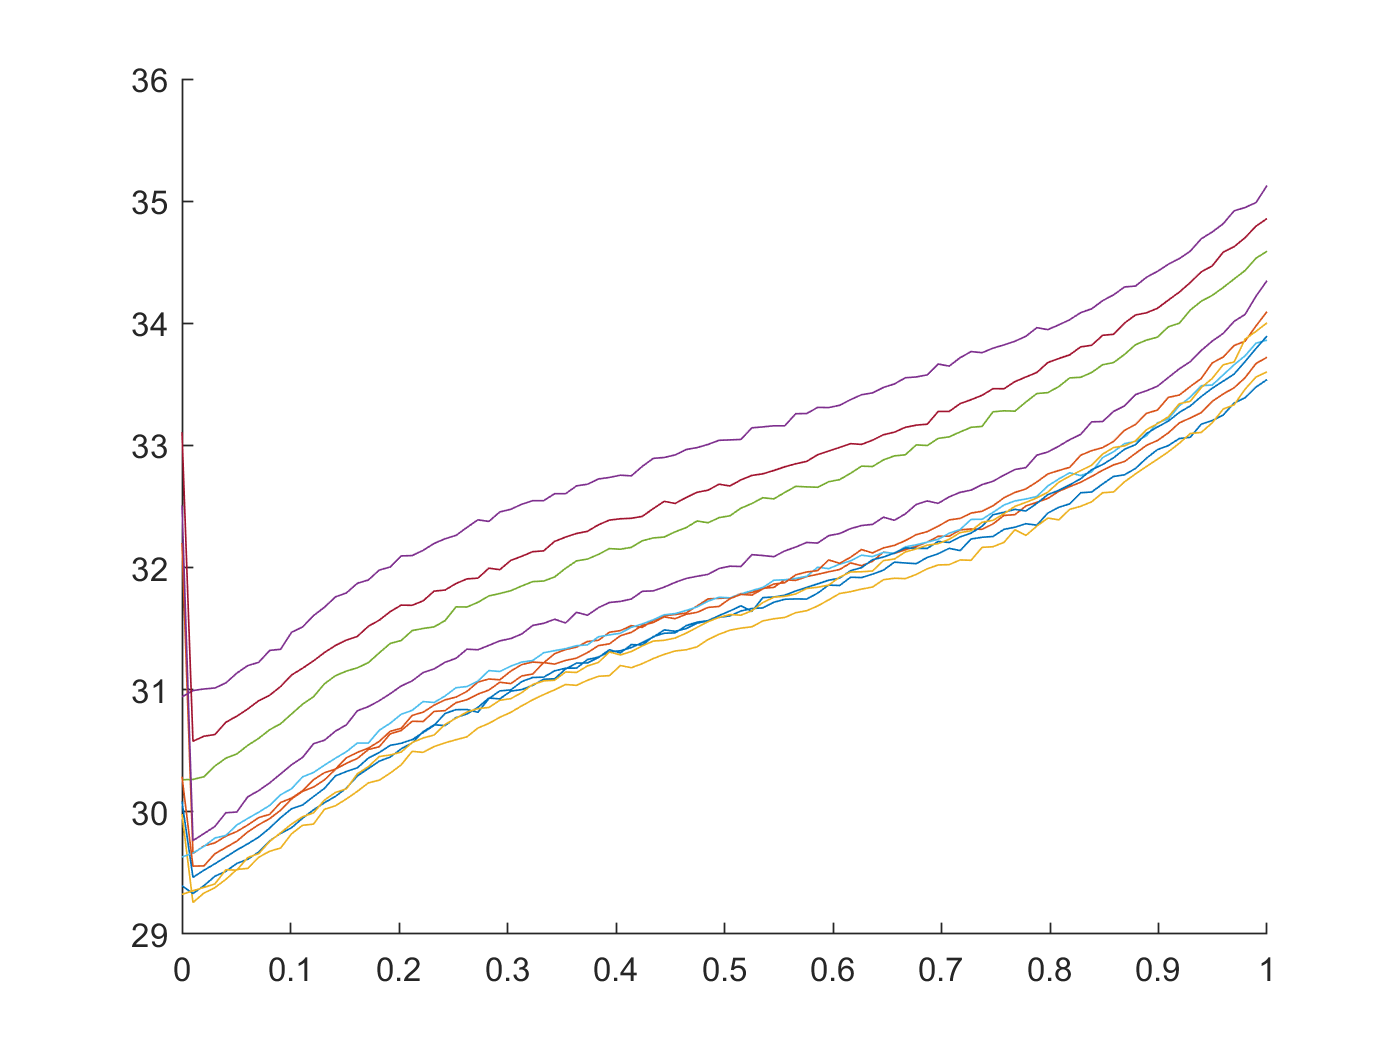


figure
hold on
for i=1:cycle_index
    if rem(i,gap) == 0
        plot(x1, VTdischarge1(i,Tindex))
    end
end
hold off

idx_summary_cycle = 1;
idx_summary_qd =  2;
idx_summary_ir = 3;
idx_summary_tavg = 4;
idx_summary_tmin = 5;
idx_summary_tmax = 6;
idx_summary_chargetime = 7;
idx_summary_qc = 8;

idx_info_key = 1;
idx_info_batchnum = 2;
idx_info_batnum = 3;
idx_info_cid = 4;
idx_info_policy = 5;
idx_info_policyreadable = 6;
%aaaa

Unrecognized function or variable 'aaaa'.

load ./batch1_info.mat
load ./batch1_data.mat





% http://localhost:8888/notebooks/data-driven-prediction-of-battery-cycle-life-before-capacity-degradation-master/Load%20Data.ipynb
for count = 1 : size(batch1_info_soc,1)
    batch1_info_soc(count,idx_info_key)
end

ans = "b1c1"

ans = "b1c2"

ans = "b1c3"

ans = "b1c4"

ans = "b1c5"

ans = "b1c6"

ans = "b1c7"

ans = "b1c8"

ans = "b1c9"

ans = "b1c10"

ans = "b1c11"

ans = "b1c12"

ans = "b1c13"

ans = "b1c14"

ans = "b1c15"

ans = "b1c16"

ans = "b1c17"

ans = "b1c18"

ans = "b1c19"

ans = "b1c20"

ans = "b1c21"

ans = "b1c22"

ans = "b1c23"

ans = "b1c24"

ans = "b1c25"

ans = "b1c26"

ans = "b1c27"

ans = "b1c28"

ans = "b1c29"

ans = "b1c30"

ans = "b1c31"

ans = "b1c32"

ans = "b1c33"

ans = "b1c34"

ans = "b1c35"

ans = "b1c36"

ans = "b1c37"

ans = "b1c38"

ans = "b1c39"

ans = "b1c40"

ans = "b1c41"

ans = "b1c42"

ans = "b1c43"

ans = "b1c44"

ans = "b1c45"

ans = "b1c46"

#batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))

batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))

#remove batteries that do not reach 80% capacity

del batch1['b1c8']

del batch1['b1c10']

del batch1['b1c12']

del batch1['b1c13']

del batch1['b1c22']

% https://kr.mathworks.com/matlabcentral/answers/34567-remove-row-with-matching-string
% https://kr.mathworks.com/matlabcentral/answers/449295-compare-to-rows-and-delete-matching-rows

del_cell= [ 8 10 12 13 22];
del_cell_str = ["b1c8", "b1c10", "b1c12", "b1c13", "b1c22" ]

del_cell_str = 1×5 string array
    "b1c8"    "b1c10"    "b1c12"    "b1c13"    "b1c22"


for i = 1:length(del_cell_str)
    I = ismember(batch1_info_soc(:,idx_info_key),del_cell_str(i) );
    %I = ismember(myarray(:, 4), 'waiting')
    batch1_info_soc(I,:)=[];
    batch1_data_soc(I,:,:)=[];
end     
size(batch1_info_soc)

ans =     41   208


size(batch1_data_soc)

ans =           41        1175         408


# There are four cells from batch1 that carried into batch2, we'll remove the data from batch2

# and put it with the correct cell from batch1

batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']

batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']

add_len = [662, 981, 1060, 208, 482];

for i, bk in enumerate(batch1_keys):

    batch1[bk]['cycle_life'] = batch1[bk]['cycle_life'] + add_len[i]

    for j in batch1[bk]['summary'].keys():

        if j == 'cycle':

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j] + len(batch1[bk]['summary'][j])))

        else:

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j]))

    last_cycle = len(batch1[bk]['cycles'].keys())

    for j, jk in enumerate(batch2[batch2_keys[i]]['cycles'].keys()):

        batch1[bk]['cycles'][str(last_cycle + j)] = batch2[batch2_keys[i]]['cycles'][jk]

del batch2['b2c7']

del batch2['b2c8']

del batch2['b2c9']

del batch2['b2c15']

del batch2['b2c16']